# Lista 1 - Parte 2b

Autor: Francisco Castro

## Introdução

    Esta parte refere-se aos dados disponíveis no arquivo *SN500574Outside.m*.

## Método TRIAD (variação)

    Executa-se os procedimentos semelhantes aos realizados na parte 1a deste exercícios computacional, referentes ao método TRIAD para determinação das condições iniciais que servirão de base para a integração das equações de atitude e de navegação a seguir.

metodoTRIAD_variacao;

## Integração numérica

    O procedimento é todo análogo, portanto, omitir-se-á a descrição para não tornar esta parte repetitiva ou uma mera cópia da anterior.

integracaoNumerica;

    A única variação, fora o método TRIAD, foi nos ganhos do controlador da estabilização do canal vertical, que foram ajustados para valores bem mais altos, uma vez que há certeza de que a IMU está parada e a referência sendo a altitude inicial é, por si só, verdadeira a cada instante (logo funciona como se um altímetro realmente estivesse dando a referência real a cada instante).

## Resultados

    Com isso, tem-se o seguinte resultado imediato da integração numérica

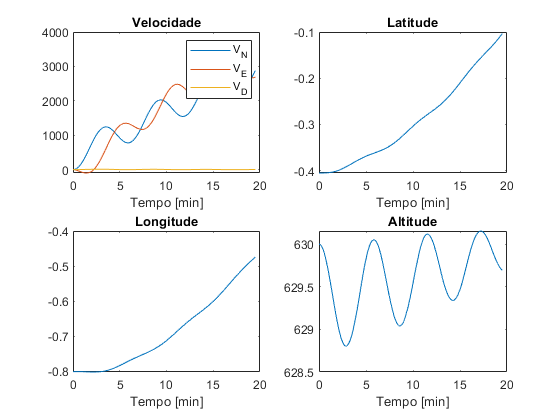

preProcessResults

## Análise da atitude computada pelo INS

**Vetor rotação (escala log)**

    Calculou-se o vetor rotação ao longo do tempo com relação ao vetor original $q0$, em [arcseg], de forma que

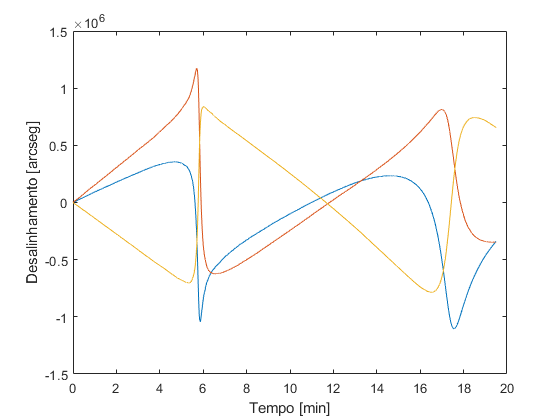

format shortG;
rotacaoTemporal = zeros(3,length(resultados.quaternion));
for i=1:length(resultados.quaternion)
    rotacaoTemporal(:,i) = vetorRotacao(resultados.quaternion(i,:), q0_base3)*180/pi*3600;
end
figure
plot(resultados.tempo/60, rotacaoTemporal)
ylabel("Desalinhamento [arcseg]");
xlabel("Tempo [min]")

**Índice de desalinhamento ao longo do tempo (escala log)**

    Analogamente, temos que os índices de desalinhamento dos quatérnions ao longo do tempo com relação ao quatérnion inicial $q_0$ são dados, em [arcseg], por

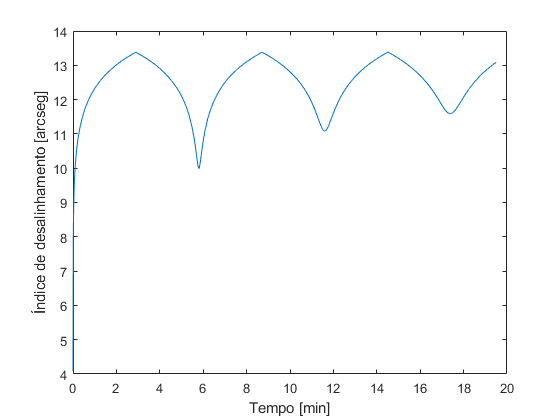

indiceDesalTemporal = zeros(1,length(resultados.quaternion));
for i=1:length(resultados.quaternion)
    indiceDesalTemporal(:,i) = indiceDesalinhamento(resultados.quaternion(i,:), q0_base3)*180/pi*3600;
end
figure
plot(resultados.tempo/60, log(indiceDesalTemporal))
ylabel("Índice de desalinhamento [arcseg]");
xlabel("Tempo [min]")

**Comparação: índice de desalinhamento [arcseg] com magnitude do desalinhamento [arcseg] computado com quaternions**

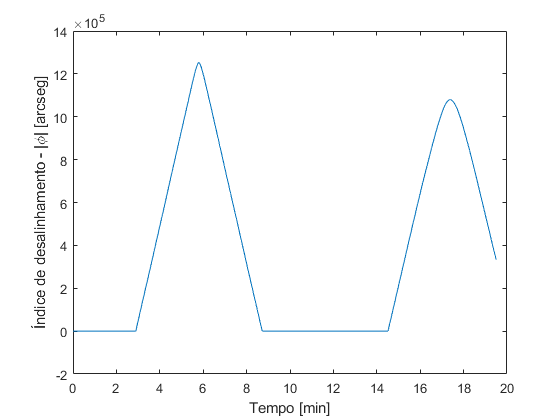

normasRotacao = zeros(1,length(resultados.quaternion));
for i=1:length(resultados.quaternion)
    normasRotacao(:,i) = norm(rotacaoTemporal(:,i));
end
format shortE
comparacao1 = normasRotacao - indiceDesalTemporal;
plot(resultados.tempo/60, comparacao1)
ylabel("Índice de desalinhamento - |\phi| [arcseg]");
xlabel("Tempo [min]")

## Análise da trajetória computada pelo INS

**Coordenadas geodésicas x cartesianas**

[xt,yt,zt] = geodToCart(...
    resultados.latitude,...
    resultados.longitude,...
    resultados.altitude,...
    modTerra);

**Resultado da altura contra tempo**

    Se tomada em relação ao ponto inicial, temos que a altura em função do tempo, em metros, pode ser dada por:

plot(resultados.tempo, zt)
xlabel("Tempo [min]");
ylabel("Altura z [m]");

**Gráfico tri-dimensional da trajetória computada pelo INS**

     A trajetória estimada pelo INS em relação ao ponto inicial, em metros, nas direções Norte, Leste e altitude a partir do instante inicial 0[s], em relação ao ponto inicial, é tal que

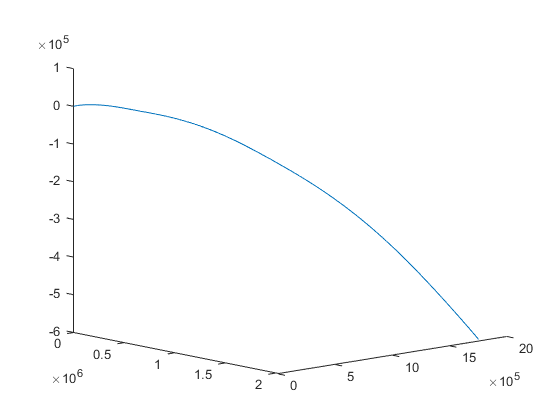

plot3(xt,yt,zt)
view([48 12])

## Perguntas

**O que ocorre com a navegação inercial usando a IMU baseada em sensores MEMS do Xsens?**

Há notavelmente baixa precisão e erros sistemáticos que, por si sós, já ocasionam grandes erros de posicionamento e desalinhamento principalmente em operações com uma grande duração, mesmo que a estimativa das condições iniciais sejam muito boas.